HW2

ruiyangz

Question1

a) a divided difference approach test

x = [0 1 2];
y = [1 3 2];
a = divided_diff_coeffs(x, y);
p = newton_eval(x, a, 1.5)

p = 2.8750

b) cos nterpolate

x = [0, 1/8, 1/4, 3/8, 1/2]

x =          0    0.1250    0.2500    0.3750    0.5000


y = cos(pi * x)

y =     1.0000    0.9239    0.7071    0.3827    0.0000



a = divided_diff_coeffs(x, y);

xstar = 3/10;

p_interp = newton_eval(x, a, xstar);

f_true = cos(pi * xstar);

% Error
err = abs(f_true - p_interp);

% Display results
fprintf('Interpolation of cos(pi*x) at x = %.2f\n', xstar);

Interpolation of cos(pi*x) at x = 0.30


fprintf('Interpolated value p(x) = %.8f\n', p_interp);

Interpolated value p(x) = 0.58785675


fprintf('True value f(x) = %.8f\n', f_true);

True value f(x) = 0.58778525


fprintf('Absolute error = %.3e\n', err);

Absolute error = 7.150e-05


c) function 2 / (1+9x^2)

f  = @(x) 2 ./ (1 + 9*x.^2);

x0 = 0.07;                      % evaluation point
ns = [2, 4, 40];                % degrees n

approx  = zeros(numel(ns),1);   % p_n(x0)
trueval = f(x0) * ones(numel(ns),1);
abserr  = zeros(numel(ns),1);

for t = 1:numel(ns)
    n = ns(t);
    xi = linspace(-1, 1, n+1);          % xi = 2*i/n - 1
    yi = f(xi);
    a  = divided_diff_coeffs(xi, yi);   % Newton DD coefficients
    approx(t) = newton_eval(xi, a, x0); % p_n(x0)
    abserr(t) = abs(approx(t) - trueval(t));
end

% Print a neat table
fprintf('\nPart (c): Interpolation of f(x)=2/(1+9x^2) at x0=%.4f\n', x0);


Part (c): Interpolation of f(x)=2/(1+9x^2) at x0=0.0700


fprintf('   n        p_n(x0)          f(x0)          |error|\n');

   n        p_n(x0)          f(x0)          |error|


for t = 1:numel(ns)
    fprintf('%4d   %14.10f  %14.10f   %10.3e\n', ns(t), approx(t), trueval(t), abserr(t));
end

   2     1.9911800000    1.9155253328    7.565e-02
   4     1.9668750652    1.9155253328    5.135e-02
  40     1.9155253271    1.9155253328    5.687e-09


d) Numerical max interpolation error on [-1,1]

f  = @(x) 2 ./ (1 + 9*x.^2);
ns = [2 4 6 8 10 12 14 16 18 20 40];

xx = linspace(-1, 1, 20001);         % ~2e4 points
fx = f(xx);

En = zeros(numel(ns),1);

for t = 1:numel(ns)
    n  = ns(t);
    xi = linspace(-1, 1, n+1);       % equispaced nodes (same as part (c))
    yi = f(xi);
    a  = divided_diff_coeffs(xi, yi);

    % Evaluate interpolant on the fine grid
    % (arrayfun calls newton_eval at each xx)
    pxx = arrayfun(@(z) newton_eval(xi, a, z), xx);

    % Max absolute error on the grid
    En(t) = max(abs(fx - pxx));
end

% Print a neat table
fprintf('\nPart (d): Max interpolation error En on [-1,1]\n');


Part (d): Max interpolation error En on [-1,1]



fprintf('   n            En (max |f - p_n|)\n');

   n            En (max |f - p_n|)



for t = 1:numel(ns)
    fprintf('%4d      %14.6e\n', ns(t), En(t));
end

   2        9.350889e-01
   4        5.963194e-01
   6        6.302535e-01
   8        7.681906e-01
  10        9.996674e-01
  12        1.351557e+00
  14        1.873958e+00
  16        2.645197e+00
  18        3.784085e+00
  20        5.469649e+00
  40        2.908908e+02


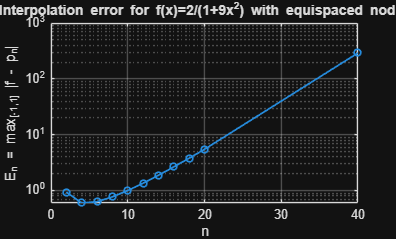


% Convergence plot
figure; semilogy(ns, En, '-o', 'LineWidth', 1.3, 'MarkerSize', 5);
grid on;
xlabel('n');
ylabel('E_n = max_{[-1,1]} |f - p_n|');
title('Interpolation error for f(x)=2/(1+9x^2) with equispaced nodes');

Question 2

Written

Question 3

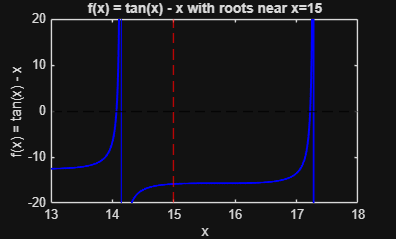

f  = @(x) tan(x) - x;     
fp = @(x) tan(x).^2;      

x = linspace(13, 17.5, 1000);
y = f(x);

figure;
plot(x, y, 'b-', 'LineWidth', 1.5); hold on;
yline(0, 'k--');     
xline(15, 'r--');    
ylim([-20 20]);      
xlabel('x');
ylabel('f(x) = tan(x) - x');
title('f(x) = tan(x) - x with roots near x=15');


x_low  = newton(f, fp, 14);
x_high = newton(f, fp, 17.25);

fprintf('x_low  = %.15f\n', x_low);

x_low  = 14.066193912831473


fprintf('x_high = %.15f\n', x_high);

x_high = 17.220755271930770



function root = newton(f, fp, x0, tol, max_iter)
    if nargin < 4, tol = 1e-12; end
    if nargin < 5, max_iter = 50; end
    
    x = x0;
    for k = 1:max_iter
        x_new = x - f(x)/fp(x);
        if abs(x_new - x) < tol
            root = x_new;
            return;
        end
        x = x_new;
    end
    error('Newton did not converge');
end

Question 4

Written

Question 5

a) implement muller method

function [x, xhist] = muller(f, x0, x1, x2, tol, maxit)

    if nargin < 6, maxit = 100; end
    if nargin < 5, tol   = 1e-12; end

    xhist = zeros(maxit+2,1);  
    xhist(1:3) = [x0; x1; x2];

    for k = 1:maxit
        f0 = f(x0);  f1 = f(x1);  f2 = f(x2);

        h0 = x1 - x0;
        h1 = x2 - x1;

        d0 = (f1 - f0) / h0;
        d1 = (f2 - f1) / h1;

        a = (d1 - d0) / (h1 + h0);
        b = a*h1 + d1;
        c = f2;

        disc = sqrt(b.^2 - 4*a*c);
        if abs(b + disc) > abs(b - disc)
            denom = b + disc;
        else
            denom = b - disc;
        end

        if abs(denom) == 0
            x3 = x2; 
        else
            x3 = x2 + (-2*c) / denom;
        end

        xhist(k+3) = x3;

        if abs(x3 - x2) <= tol*(1 + abs(x3)) || abs(f(x3)) <= tol
            xhist = xhist(1:k+3);
            x = x3;
            return;
        end

        x0 = x1;  x1 = x2;  x2 = x3;
    end

    x = x2;
    xhist = xhist(1:maxit+2);
end

b)

Since the function is a 3rd degree polynomial. I initially guess [-1, -0.5, 0] to approximate the real root. 

f = @(x) x.^3 + x + 1;

tol   = 1e-12;
maxit = 100;

[r1, hist1] = muller(f, -1.0, -0.5, 0.0, tol, maxit);

p = [1 0 1 1];
[q,~] = deconv(p, [1, -r1]);

a = q(1);
b = q(2);
c = q(3);
r2 = (-b + sqrt(b^2 - 4*a*c)/(2*a));
r3 = (-b - sqrt(b^2 - 4*a*c)/(2*a));


fprintf('root1 ≈ %.5e%+.5ei (iters=%d)\n', real(r1), imag(r1), hist1);

root1 ≈ -6.82328e-01+0.00000e+00i (iters=-1)
root1 ≈ -5.00000e-01+0.00000e+00i (iters=-6.666667e-01)
root1 ≈ -6.83190e-01-6.82324e-01i (iters=-6.823278e-01)
root1 ≈ -6.82328e-01

fprintf('root2 ≈ %.5e%+.5ei ', real(r2), imag(r2));

root2 ≈ 6.82328e-01+1.16154e+00i 

fprintf('root3 ≈ %.5e%+.5ei ', real(r3), imag(r3));

root3 ≈ 6.82328e-01-1.16154e+00i 

Question 6

Written

Question 7

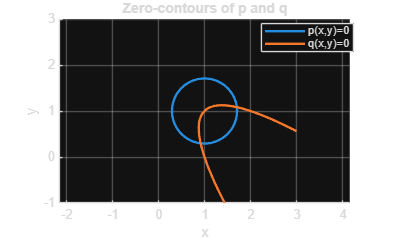

syms x y real
p = 2*x^2 + 2*y^2 - 4*x - 4*y + 3;
q = x^2 + y^2 + 2*x*y - 5*x - 3*y + 4;

%% (a) Plot zero-contours p=0 and q=0
figure('Color','w'); hold on; grid on;
fimplicit(p==0, [-1 3 -1 3], 'LineWidth',1.8);
fimplicit(q==0, [-1 3 -1 3], 'LineWidth',1.8);
axis equal; xlabel('x'); ylabel('y');
legend('p(x,y)=0','q(x,y)=0','Location','best');
title('Zero-contours of p and q');

b) Written

Question 8

a) Written 

b)

See q8_partb_.asv

c)

Choosing the paths ((p^{(i)}, p^{(j)}, p^{(k)}):

I divided the path into above and below the fire's center. I also selected the side whose starting points that were closest to the provided start points. Within that side, I looked for triples of paths whose initial points formed a non-degenerate triangle containing the start point.

**Choosing the weights α****i****�****,****α****j****�****,****α****k****�**:

The weights were determined using barycentric coordinates of the start point with respect to the chosen triangle. This guarantees that the weights are nonnegative, sum to one, and naturally represent the influence of each path.

**Deciding on a time scale for t**:

I normalized the interpolation parameter to the range t∈[0,1]. A step size of 0.01 was used, giving a good balance between smoothness of the trajectory and computational efficiency.

**Interpolation method**:

I applied piecewise-linear interpolation along the blended path. This method is simple, numerically stable, and ensures that the interpolated trajectory always remains inside the convex hull of the chosen reference paths.

d)

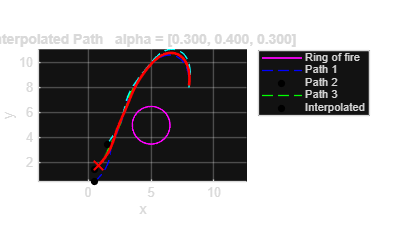

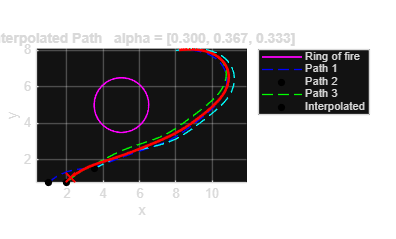

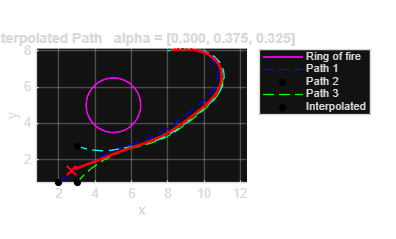

start_points = [0.8, 1.8;
                    2.2, 1.0;
                    2.7, 1.4];
for i = 1:size(start_points,1)
    q8_part_b(start_points(i,:));
end

e) 

If more obstacles are added, the main change is to extend the collision check so that the blended path is validated against all obstacles rather than just one. We could let the time step be smaller for safety improvement.